# ***Inversion_Synthetic.mlx***

Το script αυτό πραγματοποιεί την Αντιστροφή των συνθετικών δεδομένων (μικρό και μεγάλο σφάλμα). Εάν δεν προηγηθεί το τρέξιμο του script 'Misfit_Roughness.mlx', εισάγονται εκ νέου στο αντίστοιχο σημείο οι παράμετροι της Αντιστροφής.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('Inversion_Synthetic.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling.mlx'
load Workspace_ForwardModeling.mat

## Εισαγωγή Παραμέτρων Αντιστροφής

% Εισάγετε New_Par = "1": σε περίπτωση που δεν έχει προηγηθεί εκτέλεση του...
% 'Misfit_Roughness.mlx', ή επιθυμείτε τον εκ νέου καθορισμό των...
% παραμέτρων της Αντιστροφής,...
% ή New_Par = "0": εάν επιθυμείτε τη διατήρηση των ίδιων τιμών παραμέτρων.

New_Par = 0;    % --> Enter "0" or "1"

if New_Par == 0
    if exist('Inv_Par.mat','file')
        load Inv_Par.mat
    else
        disp(['Run ''Misfit_Roughness.mlx'' or' ...
            ' enter "New_Par" value "1"'])
    end

elseif New_Par == 1
    disp('Enter Inversion Parameters')

    % Εισαγωγή παραμέτρων Αντιστροφής, εάν επιλέξαμε εισαγωγή νέων παραμέτρων
    PR = 0.25;                % --> Poisson ratio (default = 0.25, όμοιο με FM)
    PS = 1.0;                 % --> Patch size [km]
    mR = 0; MR = 360;         % --> min-Max Rake [deg] (a-priori)
    MS = 50.0;                % --> Max Slip [m] (a-priori)  
    tD_A = Dip; bD_A = Dip;   % top-bottom Dip of point A (fault trace) [deg]
    tD_B = Dip; bD_B = Dip;   % top-bottom Dip of point B (fault trace) [deg]
    CN = 10000;               % --> Αριθμός κύκλων

    % Εισαγωγή επιθυμητής (βέλτιστης) παραμέτρου k (SF_sL και SF_sH)
    SF_sL = 0.18;                % --> Smoothing factor k (Synthetic Low)
    SF_sH = 0.18;                % --> Smoothing factor k (Synthetic High)
    
    % Αποθήκευση των παραμέτρων
    save ('Inv_Par.mat','PR','PS','mR','MR','MS','tD_A','bD_A','tD_B','bD_B','CN','SF_sL','SF_sH')

else
    disp('Enter "New_Par" value "0" or "1"')
    
end

# Προετοιμασία της Αντιστροφής για τα συνθετικά δεδομένα

Δημιουργούνται τα αρχεία που θα χρησιμοποιηθούν στο πρόγραμμα 'sdm2011.exe' του R. Wang, για την περίπτωση των συνθετικών δεδομένων. Η διαδικασία πραγματοποιείται δύο φορές, για τις ίδιες μετρήσεις, δίνοντας στα δεδομένα σφάλμα μετρήσεων μικρό και μεγάλo (όπως αυτό ορίστηκε).

## Synthetic Data (Low Error)

Συντάσσονται τα αρχεία input data για τρεις διευθύνσεις (North, East, Z), τα οποία αποθηκεύονται εντός του υποφακέλου 'GPS_Synthetic_L'.

% Μορφολογία σύνταξης των αρχείων input data (για κάθε διεύθυνυση...
    % [lat lon slip error])
dispacement_North = [coordinates_points 1000*uN...
    1000*repmat(sigma_uN1_t(1),points,1)];
displacement_East = [coordinates_points 1000*uE...
    1000*repmat(sigma_uE1_t(1),points,1)];
displacement_Up = [coordinates_points 1000*uZ...
    1000*repmat(sigma_uZ1_t(1),points,1)];

mkdir GPS_Synthetic_L\


% Δημιουργία αρχείου input data για uN ('coseismic-ns.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_L','coseismic-ns.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', dispacement_North');
fclose(fid);

% Δημιουργία αρχείου input data για uE ('coseismic-ew.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_L','coseismic-ew.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_East');
fclose(fid);

% Δημιουργία αρχείου input data για uZ ('coseismic-ud.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_L','coseismic-ud.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_Up');
fclose(fid);

Δημιουργείται και το input αρχείο '**synthetic_data_L.inp**' των synthetic data εντός του υποφακέλου 'sdm2011'.

    % Σύνθεση του input αρχείου 'synthetic_data_L.inp'        
    fid = fopen(fullfile(pwd,'sdm2011','synthetic_data_L.inp'), 'wt');
    fprintf(fid, [' 1\n ' ...
        num2str(PR) '\n' ...
        ' 1\n' ...
        ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
        num2str(PS) '\n ' ...
        num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
        ' 2\n ' ...
        num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
        num2str(bD_A) '\n ' ...
        num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
        num2str(bD_B) '\n ' ...
        ' 3 1.0 0\n' ...
        ' ''../GPS_Synthetic_L/coseismic-ns.txt'' ' ...
        ' ''../GPS_Synthetic_L/coseismic-ns.txt''\n' ...
        ' 1.00 0 1 90.0 0.0\n' ...
        ' ''../GPS_Synthetic_L/coseismic-ew.txt'' ' ...
        ' ''../GPS_Synthetic_L/coseismic-ew.txt''\n' ...
        ' 1.00 0 1 90.0 90.0\n' ...
        ' ''../GPS_Synthetic_L/coseismic-ud.txt'' ' ...
        ' ''../GPS_Synthetic_L/coseismic-ud.txt''\n' ...
        ' 1.00 0 1 0.0 0.0\n' ...
        ' ' num2str(CN) '\n' ...
        ' 1 ' num2str(SF_sL) '\n' ...
        ' ''synthetic_slipL.dat''\n' ...
        ' ''synthetic_outputL-un.dat'' ''synthetic_outputL-ue.dat''' ...
        ' ''synthetic_outputL-uz.dat''']);
    fclose(fid);

## Synthetic Data (High Error)

Συντάσσονται τα αρχεία input data για τρεις διευθύνσεις (North, East, Z), τα οποία αποθηκεύονται εντός του υποφακέλου 'GPS_Synthetic_Η'.

% Μορφολογία σύνταξης των αρχείων input data (για κάθε διεύθυνυση...
    % [lat lon slip error]
dispacement_North = [coordinates_points 1000*uN...
    1000*repmat(sigma_uN2_t(1),points,1)];
displacement_East = [coordinates_points 1000*uE...
    1000*repmat(sigma_uE2_t(1),points,1)];
displacement_Up = [coordinates_points 1000*uZ...
    1000*repmat(sigma_uZ2_t(1),points,1)];

mkdir GPS_Synthetic_H\


% Δημιουργία αρχείου input data για uN ('coseismic-ns.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_H','coseismic-ns.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', dispacement_North');
fclose(fid);

% Δημιουργία αρχείου input data για uE ('coseismic-ew.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_H','coseismic-ew.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_East');
fclose(fid);

% Δημιουργία αρχείου input data για uZ ('coseismic-ud.txt')
fid = fopen(fullfile(pwd,'GPS_Synthetic_H','coseismic-ud.txt'), 'wt');
fprintf(fid, '%10.6f %10.6f %10.6f %10.8f\n', displacement_Up');
fclose(fid);

Δημιουργείται και το input αρχείο '**synthetic_data_H.inp**' των synthetic data εντός του υποφακέλου 'sdm2011'.    

    % Σύνθεση του input αρχείου 'synthetic_data_Η.inp'  
    fid = fopen(fullfile(pwd,'sdm2011','synthetic_data_H.inp'), 'wt');
    fprintf(fid, [' 1\n ' ...
        num2str(PR) '\n' ...
        ' 1\n' ...
        ' 1 ' num2str(Depth) ' ' num2str(Wid) ' ' num2str(Strike) ' ' ...
        num2str(PS) '\n ' ...
        num2str(mR) ' ' num2str(MR) ' ' num2str(MS) '\n' ...
        ' 2\n ' ...
        num2str(lat_A) ' ' num2str(long_A) ' ' num2str(tD_A) ' ' ...
        num2str(bD_A) '\n ' ...
        num2str(lat_B) ' ' num2str(long_B) ' ' num2str(tD_B) ' ' ...
        num2str(bD_B) '\n ' ...
        ' 3 1.0 0\n' ...
        ' ''../GPS_Synthetic_H/coseismic-ns.txt'' ' ...
        ' ''../GPS_Synthetic_H/coseismic-ns.txt''\n' ...
        ' 1.00 0 1 90.0 0.0\n' ...
        ' ''../GPS_Synthetic_H/coseismic-ew.txt'' ' ...
        ' ''../GPS_Synthetic_H/coseismic-ew.txt''\n' ...
        ' 1.00 0 1 90.0 90.0\n' ...
        ' ''../GPS_Synthetic_H/coseismic-ud.txt'' ' ...
        ' ''../GPS_Synthetic_H/coseismic-ud.txt''\n' ...
        ' 1.00 0 1 0.0 0.0\n' ...
        ' ' num2str(CN) '\n' ...
        ' 1 ' num2str(SF_sH) '\n' ...
        ' ''synthetic_slipH.dat''\n' ...
        ' ''synthetic_outputH-un.dat'' ''synthetic_outputH-ue.dat''' ...
        ' ''synthetic_outputH-uz.dat''']);
    fclose(fid);

# Αντιστροφή συνθετικών μετρήσεων

## Low Error

Βάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' με τα συνθετικά δεδομένα με μικρό σφάλμα ('synthetic_data_L.inp').

cd sdm2011
commandfile = fopen('commandfile.txt','wt');
fprintf(commandfile,'synthetic_data_L.inp');
fclose(commandfile);
system('sdm2011.exe < commandfile.txt');

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

delete commandfile.txt
cd ..\.

## High Error

Βάζουμε τη matlab να τρέξει το πρόγραμμα 'sdm2011.exe' με τα συνθετικά δεδομένα με μεγάλο σφάλμα ('synthetic_data_H.inp').

cd sdm2011
commandfile = fopen('commandfile.txt','wt');
fprintf(commandfile,'synthetic_data_H.inp');
fclose(commandfile);
system('sdm2011.exe < commandfile.txt');

  ####################################################### 
  #                                                     # 
  #                   Welcome to                        # 
  #                                                     # 
  #                                                     # 
  #              SSSS     DDDD      M   M               # 
  #             S         D   D     M M M               # 
  #              SSS      D   D     M M M               # 
  #                 S     D   D     M   M               # 
  #             SSSS      DDDD      M   M               # 
  #                                                     # 
  #                   * * * * * * *                     # 
  # --------------------------------------------------- # 
  #                 for inverting                       # 
  #        slip distribution on fault plane             # 
  #         from surface deformation data               # 
  #     by the Steepst Descent (or Gradient) Method     

delete commandfile.txt
cd ..\.

# Απεικόνιση "προβλέψεων"

## Low Error

Data_Points = importdata('synthetic_outputL-ue.dat');

% Εισαγωγή των "προβλέψεων" για τους σταθμούς GPS
inv_uN1 = Data_Points.data(:,6);
inv_uE1 = Data_Points.data(:,7);
inv_uZ1 = Data_Points.data(:,8);

Απεικονίζονται οι "προβλέψεις" μαζί με τα συνθετικά δεδομένα στο επίπεδο East, North

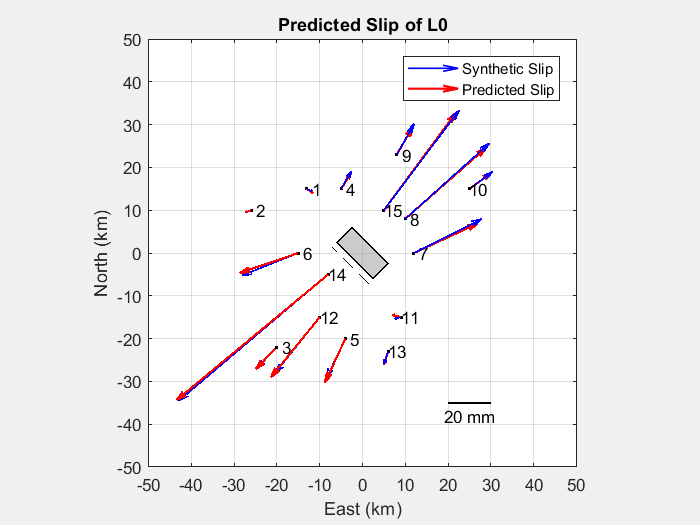

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση σημείων - σταθμών GPS
plot3(E,N,Z,'.k')
text(E,N,Z,points_names);

% Απεικόνιση των συνθετικών δεδομένων
p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,uZ*Slip_Scale,'b',...
    'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS
p2 = quiver3(E,N,Z,inv_uE1*Slip_Scale/1000,inv_uN1*Slip_Scale/1000,...
    inv_uZ1*Slip_Scale/1000,'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);

% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους του μέτρου slip
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50 -20 20])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('Predicted Slip of L0')

Και για τις κατακόρυφες ολισθήσεις:

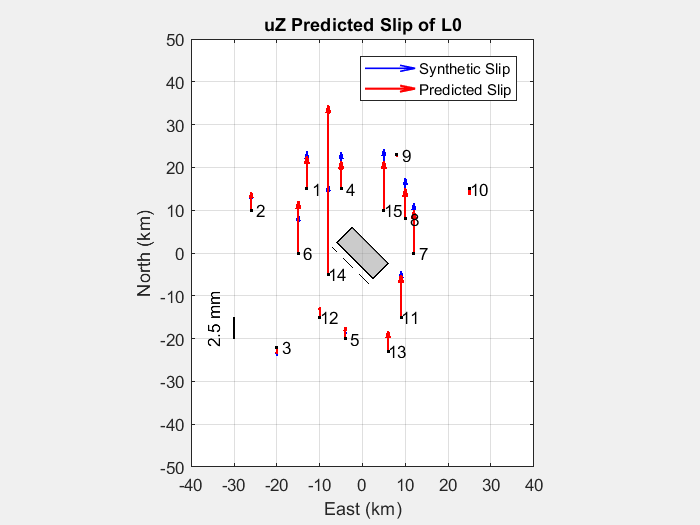

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0); 
hold on

% Απεικόνιση των σημείων - σταθμών
plot3(E,N,Z,'.k')    
text(E,N,Z,points_names);

% Απεικόνιση των συνθετικών δεδομένων
p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,zeros(points,1),'b',...
    'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS
p2 = quiver3(E,N,Z,zeros(points,1),inv_uZ1*Slip_Scale_z/1000,...
    zeros(points,1),'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);

% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Τα ticks των αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Δημιουργία μπάρας κλίμακας για το μέγεθος των ολισθήσεων
obj = scalebar_ed1;
obj.XLen = 0; obj.YLen = 5;
obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
obj.hTextY_Pos = [-5,-2];
obj.Position = [-30 -20];

% Labels, εύρος αξόνων, γωνία προβολής και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-40 40 -50 50])  % --> Μεταβάλλω ανάλογα
view([0 90]);                   % Για προβολή από πάνω
title('uZ Predicted Slip of L0')

Και σε κατακόρυφη προβολή με το σφάλμα μετρήσεων:

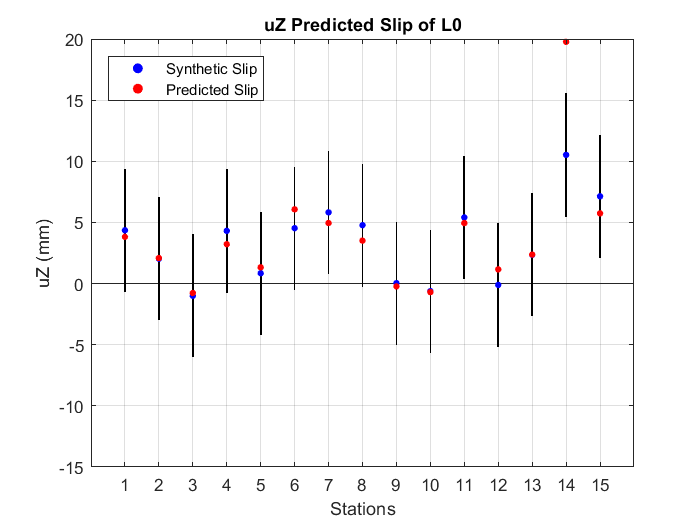

figure()

% Απεικόνιση γραμμών του εύρους σφάλματος [-σ,σ]
vert_slip1 = [uZ - sigma_uZ1, repmat(2*sigma_uZ1,points,1)]*10^6;
h = bar(vert_slip1,0.02,'stacked');
set(h(1), 'Visible','off')
hold on

% Απεικόνιση συνθετικών κατακόρυφων ολισθήσεων
p1 = scatter(1:points,uZ*10^6,15,'filled','b');

% Απεικόνιση "προβλέψεων" κατακόρυφης ολίσθησης
p2 = scatter(1:points,inv_uZ1*1000,15,'filled','r');
grid on
 
% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northwest';
   
% Ticks, Labels και τίτλος
xticks(1:points)
yticks(-500:5:500)
axis([0 points+1 -15 20]) % --> Μεταβάλλω ανάλογα ή αφαιρώ
xlabel('Stations'); ylabel('uZ (mm)')
title('uZ Predicted Slip of L0');

## High Error

Data_Points = importdata('synthetic_outputH-ue.dat');

% Εισαγωγή των "προβλέψεων" για τους σταθμούς GPS
inv_uN2 = Data_Points.data(:,6);
inv_uE2 = Data_Points.data(:,7);
inv_uZ2 = Data_Points.data(:,8);


Απεικονίζονται οι "προβλέψεις" μαζί με τα συνθετικά δεδομένα στο επίπεδο East, North.

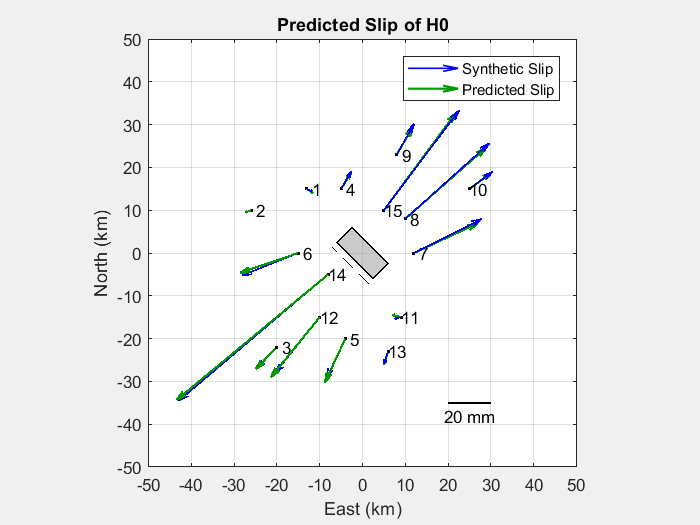

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση των σημείων - σταθμών GPS
plot3(E,N,Z,'.k')
text(E,N,Z,points_names);

% Απεικόνιση των συνθετικών δεδομένων
p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,uZ*Slip_Scale,'b',...
    'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS
p2 = quiver3(E,N,Z,inv_uE2*Slip_Scale/1000,inv_uN2*Slip_Scale/1000,...
    inv_uZ2*Slip_Scale/1000,'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);
p2.Color = [0 0.6 0];

% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους των τιμών ολίσθησης
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50 -20 20])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('Predicted Slip of H0')

Και για τις κατακόρυφες ολισθήσεις:

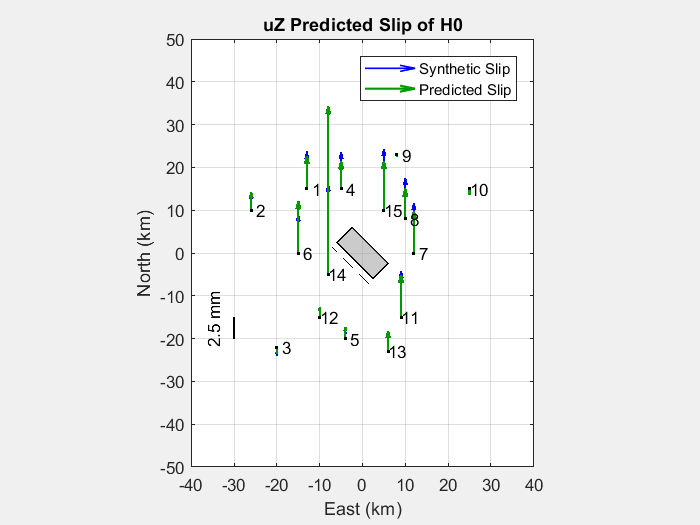

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση των σημείων - σταθμών GPS
plot3(E,N,Z,'.k')
text(E,N,Z,points_names);

% Απεικόνιση των συνθετικών δεδομένων
p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,zeros(points,1),'b',...
    'AutoScale','off','MaxHeadSize',0.1, 'LineWidth',1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS
p2 = quiver3(E,N,Z,zeros(points,1),inv_uZ2*Slip_Scale_z/1000,...
    zeros(points,1),'AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);
p2.Color = [0 0.6 0];

% Υπόμνημα
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους των τιμών ολίσθησης
obj = scalebar_ed1;
obj.XLen = 0; obj.YLen = 5;
obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
obj.hTextY_Pos = [-5,-2];
obj.Position = [-30,-20];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-40 40 -50 50])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('uZ Predicted Slip of H0')

Και σε κατακόρυφη προβολή μαζί με το σφάλμα:

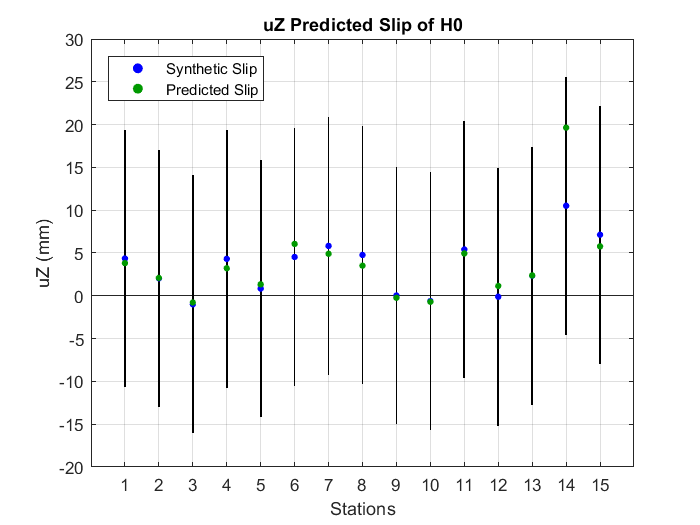

figure()

% Απεικόνιση γραμμών του εύρους σφάλματος [-σ,σ]
vert_slip1 = [uZ - sigma_uZ2, repmat(2*sigma_uZ2,points,1)]*10^6;
h = bar(vert_slip1,0.02,'stacked');
set(h(1), 'Visible','off')
hold on

% Απεικόνιση συνθετικών κατακόρυφων ολισθήσεων
p1 = scatter(1:points,uZ*10^6,15,'filled','b');

% Απεικόνιση "προβλέψεων" κατακόρυφης ολίσθησης
p2 = scatter(1:points,inv_uZ2*1000,15,[0 0.6 0],'filled');
grid on

% Υπόμνημα    
leg = legend([p1 p2],{'Synthetic Slip','Predicted Slip'});
leg.AutoUpdate = 'off';
leg.Location = 'northwest';
  
% Ticks, Labels και τίτλος
xticks(1:points)
yticks(-500:5:500)
axis([0 points+1 -20 30]) % --> Μεταβάλλω ανάλογα ή αφαιρώ
xlabel('Stations'); ylabel('uZ (mm)')
title('uZ Predicted Slip of H0');

## Low - High Error

Γίνεται απεικόνιση των "προβλέψεων" της Αντιστροφής των συνθετικών δεδομένων με μικρό και μεγάλο σφάλμα για σύγκριση, στο επίπεδο East, North.

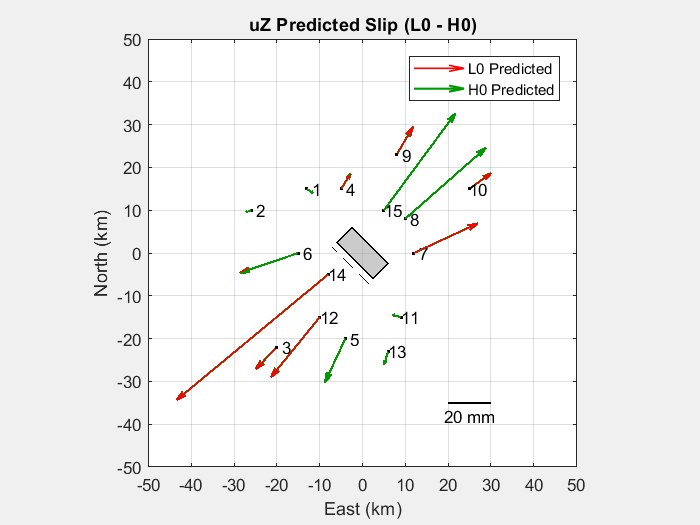

figure()

% Απεικόνιση ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση σημείων - σταθμών GPS
plot3(E,N,Z,'.k')
text(E,N,Z,points_names);

% Απεικόνιση ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS για μικρό σφάλμα
p1 = quiver3(E,N,Z,inv_uE1*Slip_Scale/1000,inv_uN1*Slip_Scale/1000,...
    inv_uZ1*Slip_Scale/1000,'r','AutoScale','off','MaxHeadSize',0.1,...
    'LineWidth',1);

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS για μεγάλο σφάλμα
p2 = quiver3(E,N,Z,inv_uE2*Slip_Scale/1000,inv_uN2*Slip_Scale/1000,...
    inv_uZ2*Slip_Scale/1000, 'AutoScale','off','MaxHeadSize',0.1,...
    'LineWidth',1.3);
p2.Color = [0 0.6 0];

% Υπόμνημα
leg = legend([p1 p2],{'L0 Predicted','H0 Predicted'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους των τιμών ολίσθησης
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50 -20 20])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('uZ Predicted Slip (L0 - H0)')

Για τις κατακόρυφες ολισθήσεις:

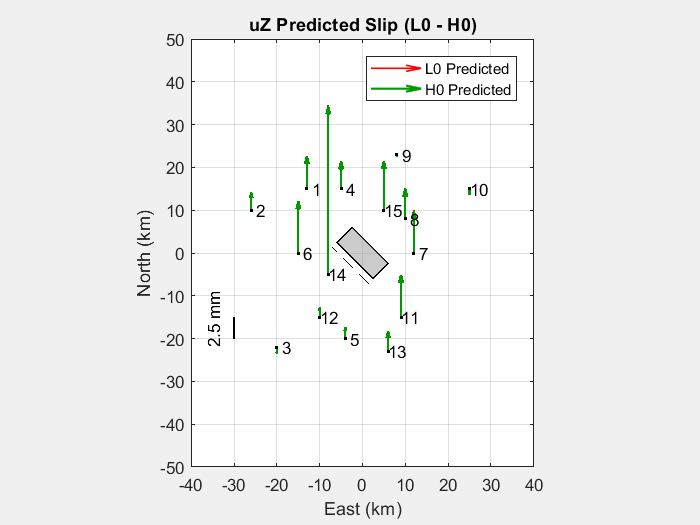

figure()

% Απεικόνιση ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση σημείων - σταθμών GPS
plot3(E,N,Z,'.k')
text(E,N,Z,points_names);

% Απεικόνιση ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS για μικρό σφάλμα
p1 = quiver3(E,N,Z,zeros(points,1),inv_uZ1*Slip_Scale_z/1000,...
    zeros(points,1),'r','AutoScale','off','MaxHeadSize',0.1,...
    'LineWidth',1);

% Απεικόνιση των "προβλέψεων" slip στους σταθμους GPS για μεγάλο σφάλμα
p2 = quiver3(E,N,Z,zeros(points,1),inv_uZ2*Slip_Scale_z/1000,...
    zeros(points,1), 'AutoScale','off','MaxHeadSize',0.1,...
    'LineWidth',1.3);
p2.Color = [0 0.6 0];

% Υπόμνημα
leg = legend([p1 p2],{'L0 Predicted','H0 Predicted'});
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Ticks αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Κλίμακα μεγέθους των τιμών ολίσθησης
obj = scalebar_ed1;
obj.XLen = 0; obj.YLen = 5;
obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
obj.hTextY_Pos = [-5,-2];
obj.Position = [-30 -20];

% Labels, εύρος αξόνων, γωνία θέασης και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-40 40 -50 50])  % Μεταβάλλω ανάλογα
view([0 90]);          % Για κατακόρυφη προβολή
title('uZ Predicted Slip (L0 - H0)')

Και σε κατακόρυφη προβολή, μαζί με τις συνθετικές μετρήσεις:

figure()

% Απεικόνιση συνθετικών κατακόρυφων δεδομένων - "προβλέψεων" 
    % (μικρό-μεγάλο σφάλμα) κατακόρυφων ολισθήσεων (μορφή stems)
p1 = stem(1:points,[uZ*10^6 inv_uZ1*1000 inv_uZ2*1000],'filled',...
    'MarkerSize',4,'LineStyle','--');

% Υπόμνημα
leg = legend(p1,{'Synthetic Slip','Predicted of L0',...
    'Predicted of H0'});
leg.AutoUpdate = 'off';
leg.Location = 'northwest';

% Ticks, Labels και τίτλος
grid on
xticks(1:points);
xlabel('Stations'); ylabel('uZ (mm)')
title('uZ Predicted Slip (L0 - H0)');

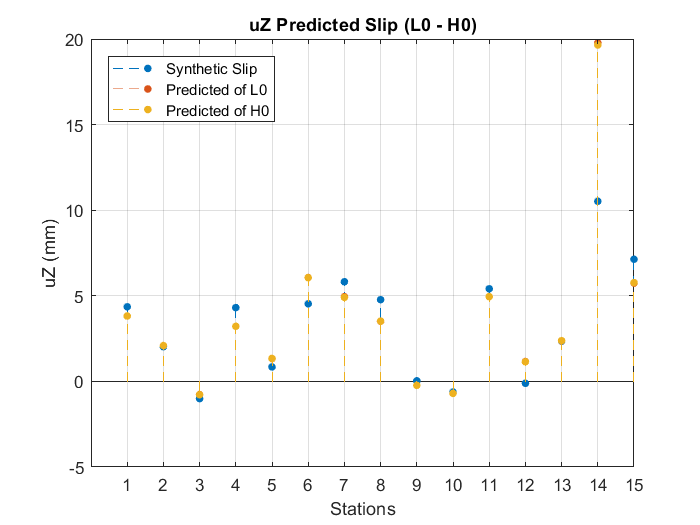

% Αποθήκευση του Workspace 
save Workspace_Inversion_Synthetic.mat

Παρατηρούμε πως η προσέγγιση είναι αρκετά καλή, ενώ είναι σχεδόν πανομοιότυπες οι περιπτώσεις χαμηλού και υψηλού σφάλματος.